***Satellite Rendesvous Demonstration ***

A **satellite rendezvous is when two spacecraft are brought close together** while both are moving at thousands of miles per hour around Earth. Astronauts need to do this when traveling from Earth to the International Space Station. Instead of heading straight for the target, the approaching satellite uses small engine burns to slowly match the target’s speed and altitude. Below is a demonstration of the process.

clear;clc;close all

%%
% figure
% for i = [1:100]
%     t = linspace(0, 10+i, 10+i);
%     y = sin(t);
%     plot(t, y)
%     hold on
%     pause(1)
% end

At the start of a satellite meeting, two spacecraft can be very far apart. **To bring them closer, engineers use a method called a Hohmann transfer. **Instead of flying straight at the target, the chasing spacecraft changes its path with two engine burns. The first burn puts it on a new path that crosses the target’s orbit, letting gravity help with most of the work. The second burn makes sure the spacecraft matches the target’s height and speed at the right time. This way, the spacecraft gets closer using less fuel, making it ready for the final meeting steps.

***Select the Orbit Parameters of the Target Spacecraft here:***

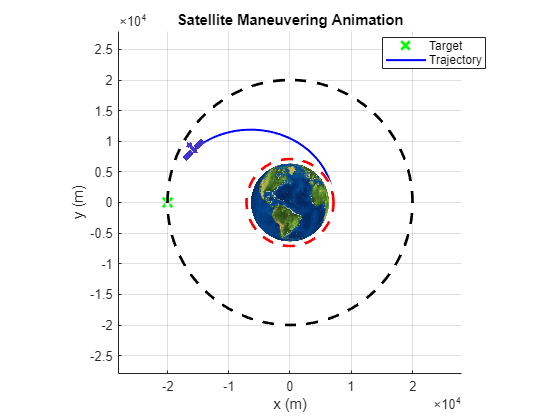

orbitSemiMajorAxis1 =20000; %km
%orbitTrueAnamoly =180;% degrees
orbitSemiMajorAxis0 =7100; %km

warning('off', 'MATLAB:ode45:IntegrationTolNotMet');
orbitAnimation2D

figure;
set(gcf, 'Color', 'w');
hold on; axis equal; grid on;
% Circle parameters
h = 0; % x-coordinate of center
k = 0; % y-coordinate of center

% Implicit equation: (x-h)^(2) + (y-k)^(2) - r^(2) = 0

xlabel('x (m)'); ylabel('y (m)');
title('Satellite Maneuvering Animation');

% Set axis limits with some padding
% x_min = min(x(:,1)); x_max = max(x(:,1));
% y_min = min(x(:,2)); y_max = max(x(:,2));
x_min = -orbitSemiMajorAxis1; x_max = orbitSemiMajorAxis1;
y_min = -orbitSemiMajorAxis1; y_max = orbitSemiMajorAxis1;
dx = x_max - x_min; if dx==0, dx=1; end
dy = y_max - y_min; if dy==0, dy=1; end

% Import and display Earth image
    % Check if image exists
    earthImgFile = 'earth_PNG3.png';
    if exist(earthImgFile, 'file')
        % Read image and alpha channel if available
        [img, ~, alpha] = imread(earthImgFile);
   
        % Constants for Earth
        rEarth = 6378; % km
   
        % Plot image with correct extent
        % XData: [-rEarth, rEarth], YData: [rEarth, -rEarth] (top-down)
        hEarth = image('CData', img, 'XData', [-rEarth rEarth], 'YData', [rEarth -rEarth]);
   
        % Apply transparency if alpha channel exists
        if ~isempty(alpha)
            set(hEarth, 'AlphaData', alpha);
        end
   
        % Ensure axis direction is normal for cartesian plot
        set(gca, 'YDir', 'normal');
    else
        warning('Earth image file "%s" not found.', earthImgFile);
    end
   
    % Plot the target state (origin)
    plot(-rf, 0, 'gx', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Target');
   
    % Create animated line for trajectory and marker for satellite
    hTraj = animatedline('LineWidth', 1.5, 'Color', 'b', 'DisplayName', 'Trajectory');

    % Load satellite image
    chaserImgFile = 'chaser2D.png';
    if exist(chaserImgFile, 'file')
        [satImg, ~, satAlpha] = imread(chaserImgFile);
        rSat = 2000; % Visible radius on plot (not to scale)
        % Initial position
        hSat = image('CData', satImg, ...
            'XData', x(1, 1) + [-rSat rSat], ...
            'YData', x(1, 2) + [rSat -rSat]);
        if ~isempty(satAlpha)
            set(hSat, 'AlphaData', satAlpha);
        end
    else
        hSat = plot(x(1, 1), x(1, 2), 'k.', 'MarkerSize', 20, 'DisplayName', 'Satellite');
        warning('Satellite image file "%s" not found. Using default marker.', chaserImgFile);
    end

    x_span = max(x(:,1)) - min(x(:,1));
    y_span = max(x(:,2)) - min(x(:,2));
    avg_span = (x_span + y_span) / 2;
    if avg_span == 0, avg_span = 1; end
    % Thrust vector components for plotting: direction * throttle
    u_vec_plot = u(:, 1:3) .* u(:, 4);
    u_mag = u(:, 4); % Throttle is the magnitude factor (assuming unit direction)
   
    max_u = max(u_mag);
    if max_u == 0, scale_inv = 1; else, scale_inv = (0.15 * avg_span) / max_u; end
    legend('show', 'Location', 'best');
   
   
    % Setup Video Writer
    videoFilename = 'satellite_maneuver.mp4';
    vWriter = VideoWriter(videoFilename, 'MPEG-4');
    vWriter.FrameRate = 20; % Adjust frame rate as needed
    % open(vWriter);
   
    % Loop through time steps to animate
    % Depending on the number of steps in 't', we might want to skip frames to keep video short
    nSteps = length(t);
    frameStep = max(1, floor(nSteps / 200)); % Target approx 300 frames max (~10s at 30fps)
    viscircles([0 0],[r0],'LineStyle','--','Color',"r");
    viscircles([0 0],[rf],'LineStyle','--','Color',"k");
   
    for k = 1:frameStep:nSteps
        xlim([x_min - 0.2*dx, x_max + 0.2*dx]);
        ylim([y_min - 0.2*dy, y_max + 0.2*dy]);
        addpoints(hTraj, x(k, 1), x(k, 2));
        if exist(chaserImgFile, 'file')
            set(hSat, 'XData', x(k, 1) + [-rSat rSat], 'YData', x(k, 2) + [rSat -rSat]);
        else
            set(hSat, 'XData', x(k, 1), 'YData', x(k, 2));
        end
        drawnow;
   
        axis equal;
    end

When two spacecraft are already close together, engineers **use equations called the Clohessy–Wiltshire–Hill (CWH) equations to determine how they move relative to each other in space**. Instead of going straight to the target, a spacecraft uses careful bursts from its engines to move along curved paths. Mission teams can plan safe, fuel-saving maneuvers using this understanding of such models. This helps the two spacecraft slowly get close enough for docking, inspection, or servicing.

***Select the Time Required and the Initial Distance our spacecraft is behind its target here:***

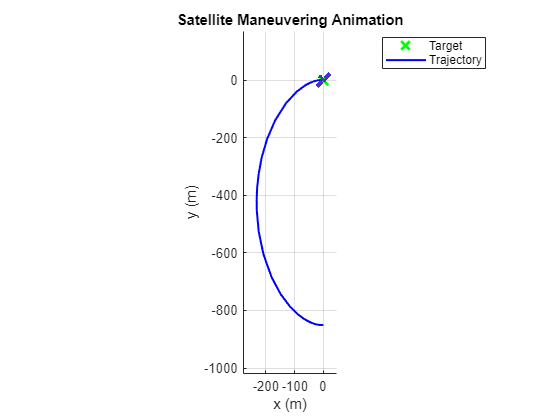

initialDistance =850; %m
meetupTime =3000;% s

optControl_singleShoot_Demo

figure;
set(gcf, 'Color', 'w');
hold on; axis equal; grid on;
xlabel('x (m)'); ylabel('y (m)');
title('Satellite Maneuvering Animation');

% Plot the target state (origin)
plot(0, 0, 'gx', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Target');

% Create animated line for trajectory and marker for satellite
hTraj = animatedline('LineWidth', 1.5, 'Color', 'b', 'DisplayName', 'Trajectory');
% hSat = plot(x(1, 1), x(1, 2), 'k.', 'MarkerSize', 20, 'DisplayName', 'Satellite');

    % Load satellite image
    chaserImgFile = 'chaser2D.png';
    if exist(chaserImgFile, 'file')
        [satImg, ~, satAlpha] = imread(chaserImgFile);
        rSat = 30; % Visible radius on plot (not to scale)
        % Initial position
        hSat = image('CData', satImg, ...
            'XData', x(1, 1) + [-rSat rSat], ...
            'YData', x(1, 2) + [rSat -rSat]);
        if ~isempty(satAlpha)
            set(hSat, 'AlphaData', satAlpha);
        end
    else
        hSat = plot(x(1, 1), x(1, 2), 'k.', 'MarkerSize', 20, 'DisplayName', 'Satellite');
        warning('Satellite image file "%s" not found. Using default marker.', chaserImgFile);
    end

% Calculate scaling for thrust vector visualization
% We want the max thrust vector to correspond to roughly 15% of the plot span
x_span = max(x(:,1)) - min(x(:,1));
y_span = max(x(:,2)) - min(x(:,2));
avg_span = (x_span + y_span) / 2;
if avg_span == 0, avg_span = 1; end
u_mag = sqrt(sum(u.^2, 2));
max_u = max(u_mag);
if max_u == 0, scale_inv = 1; else, scale_inv = (0.15 * avg_span) / max_u; end

% Initialize thrust vector (scaled)
% hThrust = quiver(x(1, 1), x(1, 2), u(1, 1)*scale_inv, u(1, 2)*scale_inv, ...
%     'r', 'LineWidth', 2, 'MaxHeadSize', 0.5, 'AutoScale', 'off', 'DisplayName', 'Thrust Direction');

legend('show', 'Location', 'best');

% Set axis limits with some padding
x_min = min(x(:,1)); x_max = max(x(:,1));
y_min = min(x(:,2)); y_max = max(x(:,2));
dx = x_max - x_min; if dx==0, dx=1; end
dy = y_max - y_min; if dy==0, dy=1; end
xlim([x_min - 0.2*dx, x_max + 0.2*dx]);
ylim([y_min - 0.2*dy, y_max + 0.2*dy]);

% Setup Video Writer
% Loop through time steps to animate
% Depending on the number of steps in 't', we might want to skip frames to keep video short
nSteps = length(t);
frameStep = max(1, floor(nSteps / 300)); % Target approx 300 frames max (~10s at 30fps)

for k = 1:frameStep:nSteps
    % addpoints(hTraj, x(k, 1), x(k, 2));
    % set(hSat, 'XData', x(k, 1), 'YData', x(k, 2));

        addpoints(hTraj, x(k, 1), x(k, 2));
        if exist(chaserImgFile, 'file')
            set(hSat, 'XData', x(k, 1) + [-rSat rSat], 'YData', x(k, 2) + [rSat -rSat]);
        else
            set(hSat, 'XData', x(k, 1), 'YData', x(k, 2));
        end
    
    % Update thrust vector
    % set(hThrust, 'XData', x(k, 1), 'YData', x(k, 2), ...
    %     'UData', u(k, 1)*scale_inv, 'VData', u(k, 2)*scale_inv);
    
    drawnow;
end